# CWRU data classification using machine learning

Name : HanMinung

Student ID : 21800773

Dep : School of Mechanical and Control Engineering

Class : Industrial AI & Automation

## Data loading

- Data loading

- Variable declaration

- Data pre - processing to generate each class

% clear

addpath('../Assignment_2/Functions');

% user defined function : allFeatures

- Each class has different number of datas.

- In needs to be processed since normal class has relatively large number of datas.

- Proper technique for data augmentation : sliding window with overlapping

- # of segements : 20,    Overlap ratio : 0.2

## Getting all feature

allFeatures();

## Statisical feature

staticFeatures

staticFeatures = 400×18 table
                       mean        std        rms        sra         aav      energy     peak        ppv        if        sf        cf        mf          sk          kt         fc          rmsf          rvf          cls   
                     ________    _______    _______    ________    _______    ______    _______    _______    ______    ______    ______    ______    __________    ______    _________   

## Complex envelop analysis

envelopFeatures

envelopFeatures = 400×37 table
                     BPFO_DE_1st    BPFO_DE_2nd    BPFO_DE_3th    BPFO_DE_4th    BPFO_DE_5th    BPFO_DE_6th    BPFO_FE_1st    BPFO_FE_2nd    BPFO_FE_3th    BPFO_FE_4th    BPFO_FE_5th    BPFO_FE_6th    BPFI_DE_1st    BPFI_DE_2nd    BPFI_DE_3th    BPFI_DE_4th    BPFI_DE_5th    BPFI_DE_6th    BPFI_FE_1st    BPFI_FE_2nd    BPFI_FE_3th    BPFI_FE_4th    BPFI_FE_5th    BPFI_FE_6th    BSF_DE_1st    BSF_DE_2nd    BSF_DE_3th    BSF_DE_4th    BSF_DE_5th    BSF_DE_6th

## Wavelet package analysis

wavletFeatures

wavletFeatures = 400×17 table
                       E1        E2        E3        E4        E5        E6        E7        E8          E9          E10         E11        E12        E13       E14        E15       E16         cls   
                     ______    ______    ______    ______    ______    ______    ______    _______    _________    ________    _______    ________    ______    ______    _______    ______    _________

## Global pool

- Global pool : includes all features of data

globalPool = [staticFeatures(:,1:end-1) envelopFeatures(:,1:end-1) wavletFeatures]

globalPool = 400×70 table
                       mean        std        rms        sra         aav      energy     peak        ppv        if        sf        cf        mf          sk          kt         fc          rmsf          rvf       BPFO_DE_1st    BPFO_DE_2nd    BPFO_DE_3th    BPFO_DE_4th    BPFO_DE_5th    BPFO_DE_6th    BPFO_FE_1st    BPFO_FE_2nd    BPFO_FE_3th    BPFO_FE_4th    BPFO_FE_5th    BPFO_FE_6th    BPFI_DE_1st    BPFI_DE_2nd    BPFI_DE_3th

## Confusion matrix

- 4 : staticFeatures / envelopFeatures / waveletFeatures / globalPool

- Function 'normalization' returns z score.  Center value 0, Standard deviation 1 

**Normalization**

normstaticFeature  = normalizeTbl(staticFeatures);
normenvelopFeature = normalizeTbl(envelopFeatures);
normwaveletFeature = normalizeTbl(wavletFeatures);
normglobalPool     = normalizeTbl(globalPool);

normglobalPool

normglobalPool = 400×70 table
                       mean        std         rms         sra         aav        energy       peak        ppv          if         sf          cf          mf          sk          kt          fc         rmsf        rvf       BPFO_DE_1st    BPFO_DE_2nd    BPFO_DE_3th    BPFO_DE_4th    BPFO_DE_5th    BPFO_DE_6th    BPFO_FE_1st    BPFO_FE_2nd    BPFO_FE_3th    BPFO_FE_4th    BPFO_FE_5th    BPFO_FE_6th    BPFI_DE_1st    BPFI_DE_2nd    B

**Training**

- kfold loss : k fold를 했을 때, 교차검증된 

- loss : 다른 특정 데이터셋에서 주로 사용하는데 유용

- 0.3 percent cvpartition

[stcTrain, stcTrainCls, stcTest, stcTestCls] = trainTest(normstaticFeature);
[envTrain, envTrainCls, envTest, envTestCls] = trainTest(normenvelopFeature);
[waveTrain, waveTrainCls, waveTest, waveTestCls] = trainTest(normwaveletFeature);
[poolTrain, poolTrainCls, poolTest, poolTestCls] = trainTest(normglobalPool);

**Classification : statistical feature**

1) KNN

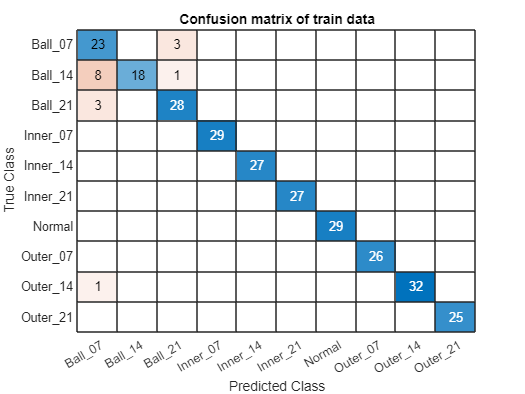

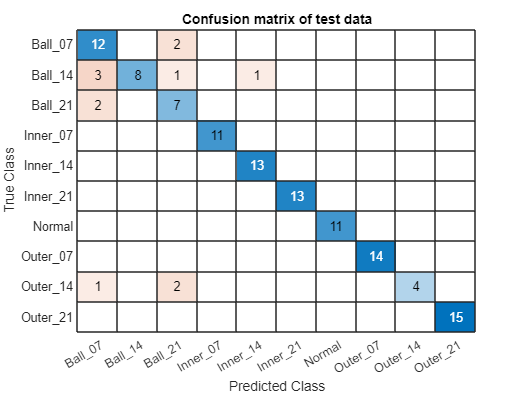

stcKNNloss = KNN(stcTrain, stcTrainCls, stcTest, stcTestCls);

2) SVM

ResubErr_SVM = 0.1179

cvErr_SVM = 0.1714

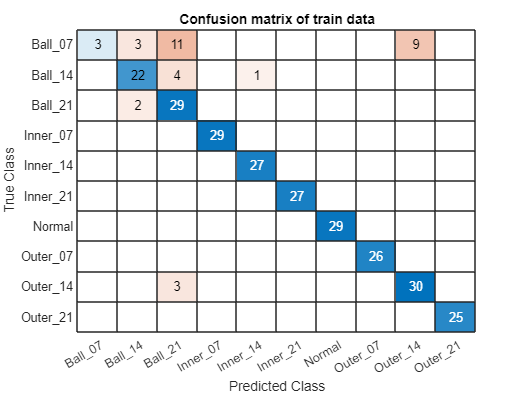

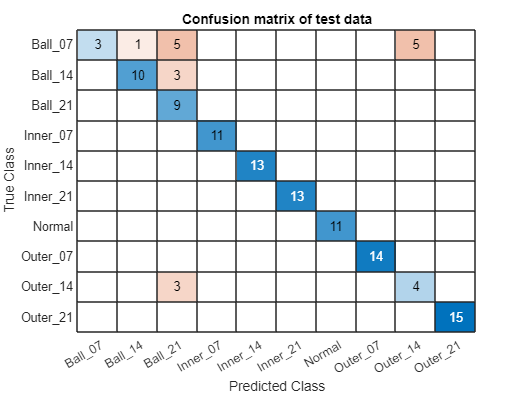

stcSVMloss = SVM(stcTrain, stcTrainCls, stcTest, stcTestCls);

3) Deicision tree

ResubErr_Tree = 0.0143

cvErrTree = 0.0750

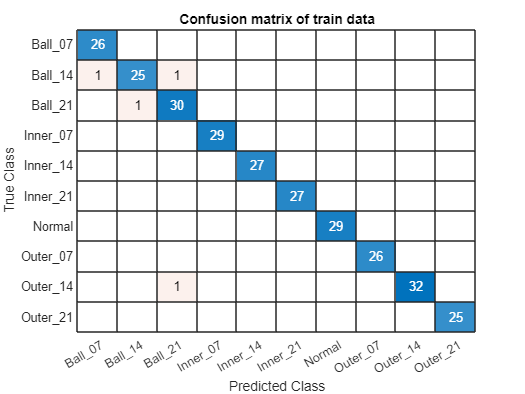

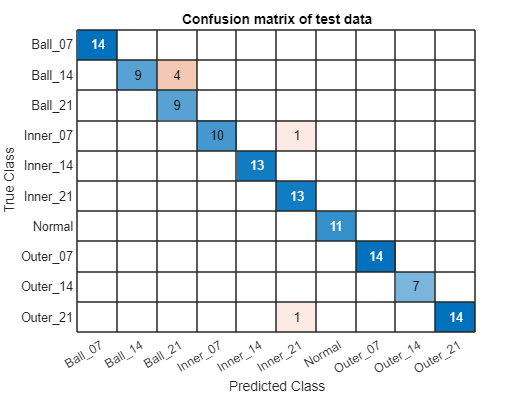

stcTREEloss = decisionTree(stcTrain, stcTrainCls, stcTest, stcTestCls);

**Classification : envelop feature**

1) KNN

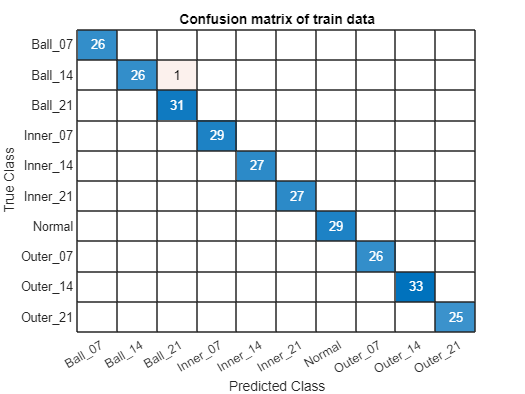

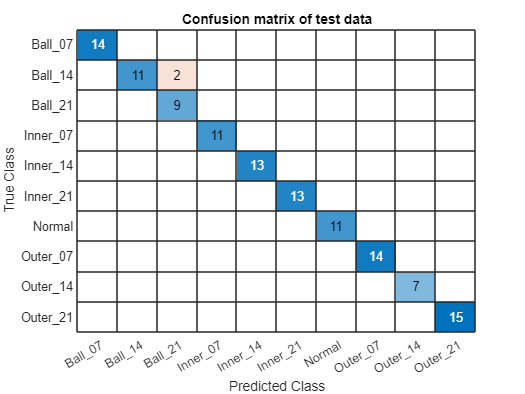

envKNNloss = KNN(envTrain, envTrainCls, envTest, envTestCls);

2) SVM

ResubErr_SVM = 0

cvErr_SVM = 0.0464

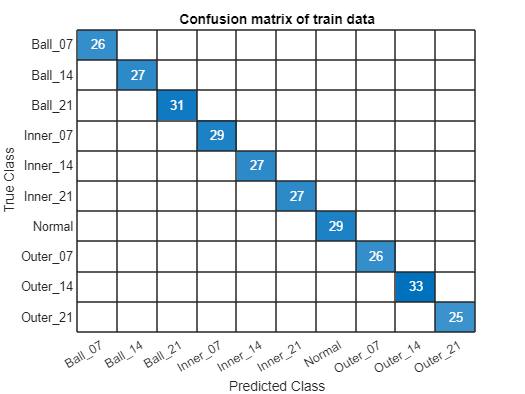

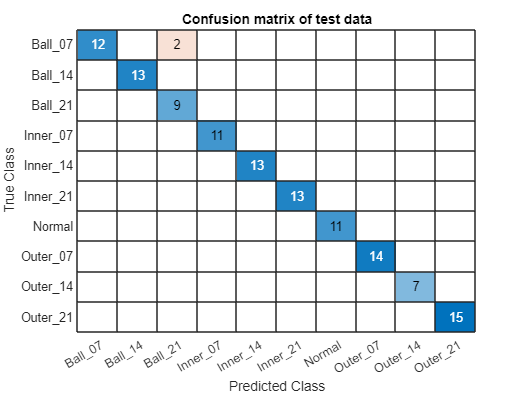

envSVMloss = SVM(envTrain, envTrainCls, envTest, envTestCls);

3) Deicision tree

ResubErr_Tree = 0.0286

cvErrTree = 0.1571

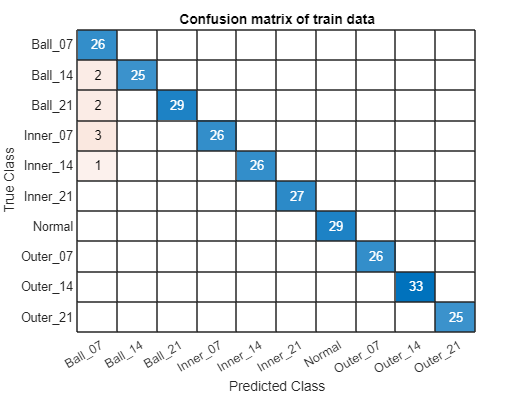

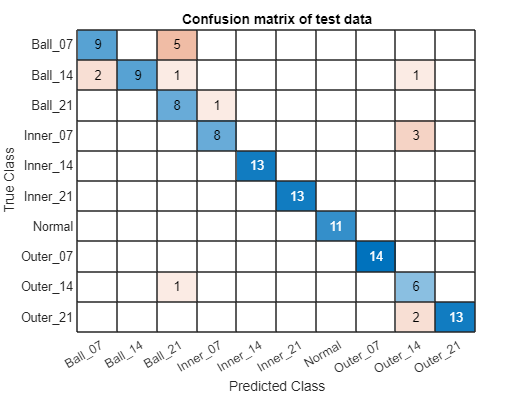

envTREEloss = decisionTree(envTrain, envTrainCls, envTest, envTestCls);

**Classification : wavelet feature**

1) KNN

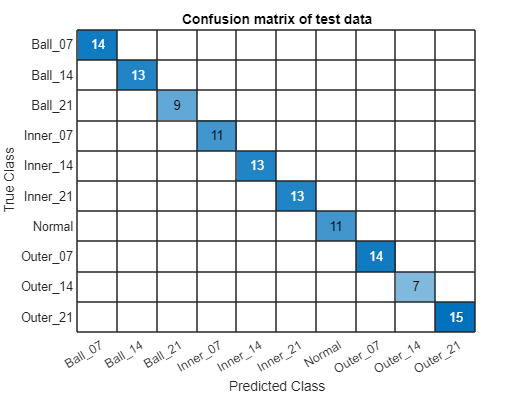

waveKNNloss = KNN(waveTrain, waveTrainCls, waveTest, waveTestCls);

2) SVM

ResubErr_SVM = 0

cvErr_SVM = 0.0071

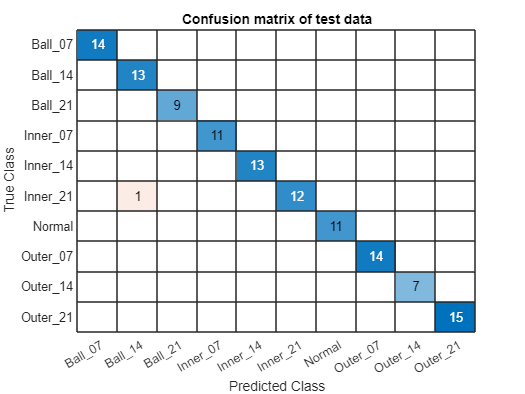

waveSVMloss = SVM(waveTrain, waveTrainCls, waveTest, waveTestCls);

3) Deicision tree

ResubErr_Tree = 0.0036

cvErrTree = 0.1107

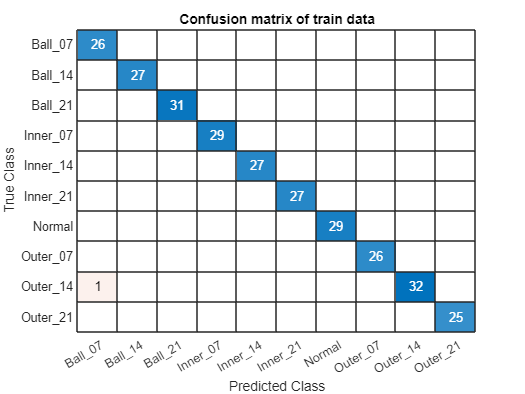

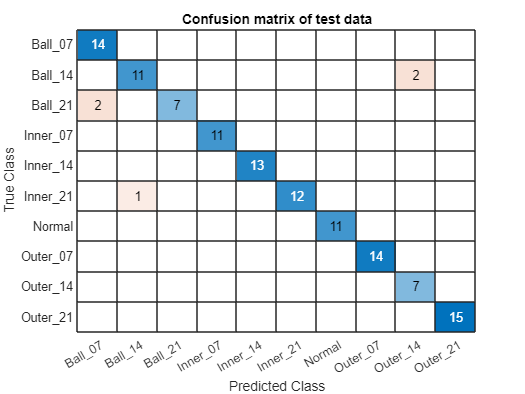

waveTREEloss = decisionTree(waveTrain, waveTrainCls, waveTest, waveTestCls);

**Classification : Global pool**

1) KNN

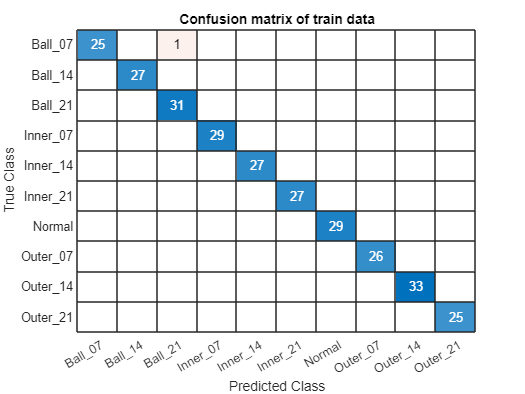

poolKNNloss = KNN(poolTrain, poolTrainCls, poolTest, poolTestCls);

2) SVM

ResubErr_SVM = 0

cvErr_SVM = 0.0036

poolSVMloss = SVM(poolTrain, poolTrainCls, poolTest, poolTestCls);

3) Deicision tree

ResubErr_Tree = 0.0107

cvErrTree = 0.0964

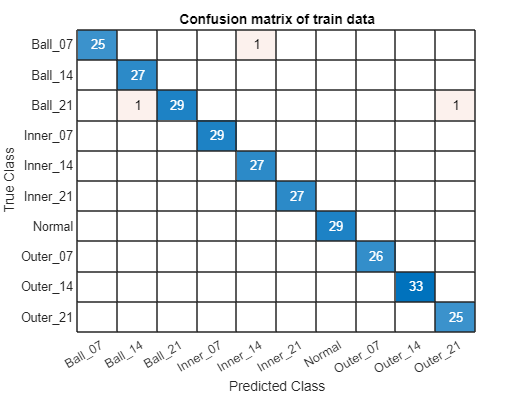

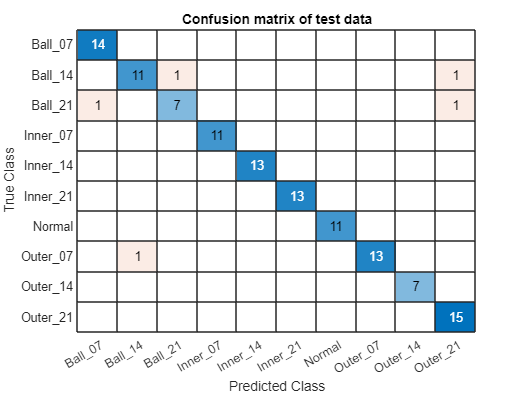

poolTREEloss = decisionTree(poolTrain, poolTrainCls, poolTest, poolTestCls);

**EX2. Feature reduction**

- Feature reduction in global pool

- Principal componene analysis, Forward selection

**PCA**

[coeff, scores_train, ~, ~, explained, pcaCenter] = pca(table2array(poolTrain));

explain_standard = 0.95;     
num = find(cumsum(explained)/sum(explained) >= explain_standard, 1)

num = 14

coeff = coeff(:,1:num);
scores_train = scores_train(:,1:num);

[n,p] = size(poolTrain);
meanX = mean(table2array(poolTrain),1);

% Xfit: in original coordinate system
Xfit = repmat(meanX,n,1) + scores_train(:,1:num)*coeff(:,1:num)';

[ntest,ptest] = size(poolTest(:,1:end));
mu = repmat(pcaCenter, ntest, 1);
global_test_pca = (table2array(poolTest(:,1:end-1)) - mu)/coeff';

- KNN

PCA_KNN_loss = KNN(scores_train, poolTrainCls, global_test_pca, poolTestCls);

- SVM

ResubErr_SVM = 0.0036

cvErr_SVM = 0.0107

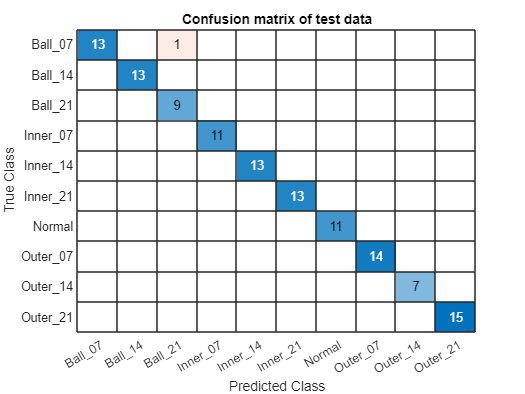

PCA_SVM_loss = SVM(scores_train, poolTrainCls, global_test_pca, poolTestCls);

- Decision Tree

ResubErr_Tree = 0.0107

cvErrTree = 0.0964

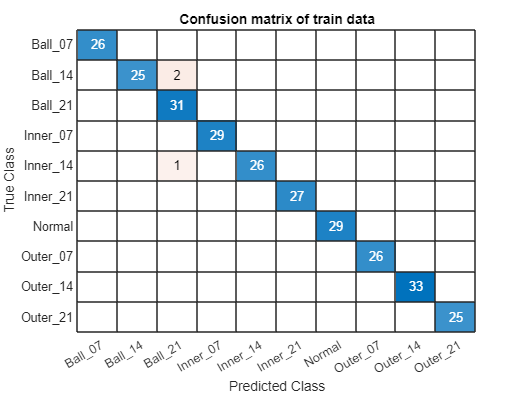

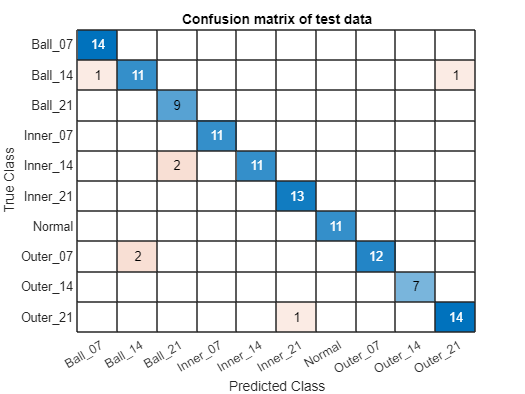

PCA_Tree_loss = decisionTree(scores_train, poolTrainCls, global_test_pca, poolTestCls);

### Forward selection

rng(0)
Y = height(poolTrain);        
cv = cvpartition(Y,'KFold',3); 

lossfun = 'mincost';
opts = statset('Display','iter');

k =1;
fun = @(XT,yT,Xt,yt)loss(fitcknn(XT,yT, 'NumNeighbors', k, 'Standardize', 1),Xt,yt, 'Lossfun', lossfun);   

rng(0)

dir = 'forward';  
[inmodel, history] = sequentialfs(fun, table2array(poolTrain), poolTrainCls, 'cv', cv, 'options',opts, 'direction', dir)

Start forward sequential feature selection:
Initial columns included:  none
Columns that can not be included:  none
Step 1, added column 16, criterion value 0.00241256
Step 2, added column 69, criterion value 0.000592119
Step 3, added column 31, criterion value 0
Final columns included:  16 31 69 


inmodel = 1×69 logical array
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0


history = struct with fields:
      In: [3×69 logical]
    Crit: [0.0024 5.9212e-04 0]


select = find(inmodel);
global_Train_select = poolTrain(:,select);
global_Test_select = poolTest(:,select);

- KNN

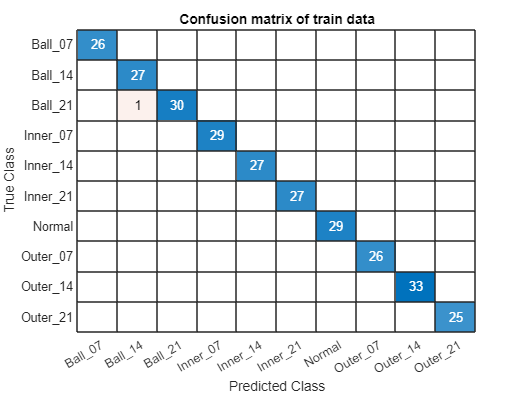

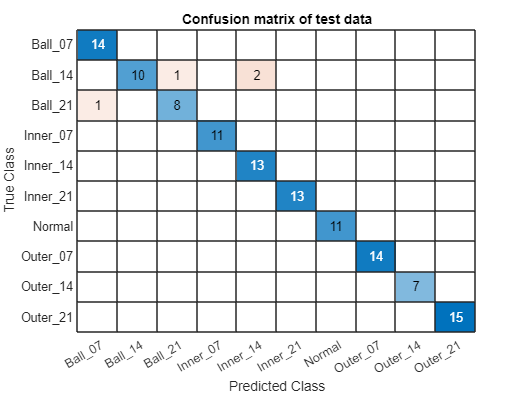

SFS_KNN_loss = 0.0346

SFS_KNN_loss = KNN(global_Train_select, poolTrainCls, global_Test_select, poolTestCls)

- SVM

ResubErr_SVM = 0.2429

cvErr_SVM = 0.3250

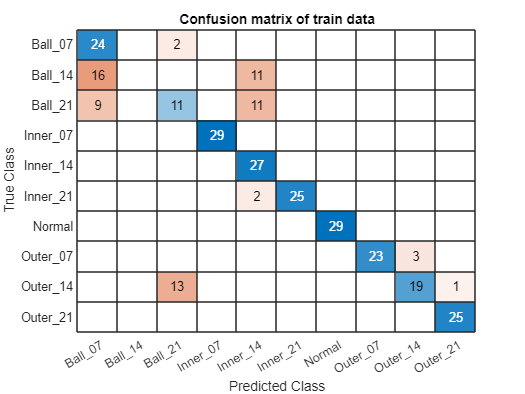

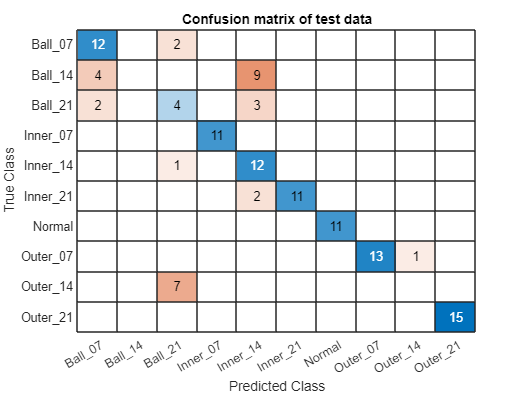

SFS_SVM_loss = 0.3179

SFS_SVM_loss = SVM(global_Train_select, poolTrainCls, global_Test_select, poolTestCls)

- Decision tree

ResubErr_Tree = 0.0214

cvErrTree = 0.0857

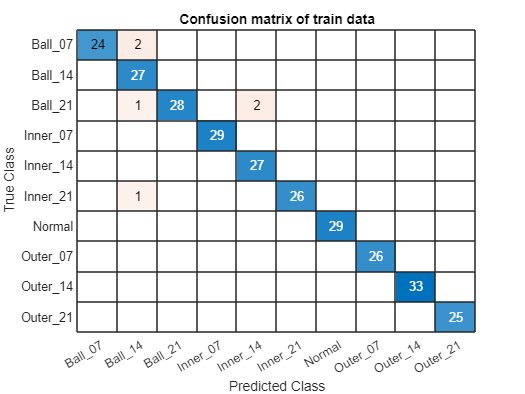

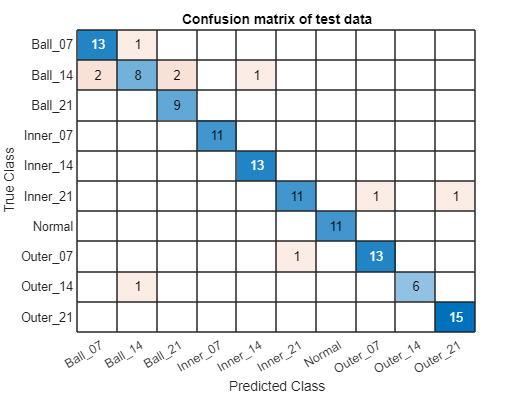

SFS_Tree_loss = 0.0820

SFS_Tree_loss = decisionTree(global_Train_select, poolTrainCls, global_Test_select, poolTestCls)

**- Table for comparing accuracy of each model**

**Compare objects : compare the each result of ( without selecting vs selecting )**

- Without selection

cmpLoss_without = [ stcKNNloss stcSVMloss stcTREEloss   ;
                    envKNNloss envSVMloss envTREEloss   ;
                    waveKNNloss waveSVMloss waveTREEloss;
                    poolKNNloss poolSVMloss poolTREEloss]

cmpLoss_without =     0.1255    0.1457    0.0450
    0.0148    0.0133    0.1321
         0    0.0074    0.0469
         0         0    0.0461


accuracy = round((1 - cmpLoss_without)*100, 2);

colName = ["KNN [%]", "SVM [%]", "Decision Tree [%]"];
rowName = ["Statistical feature", "Envelop feature", "Wavelet feature", "Global pool"];

withoutTbl = array2table(accuracy, "VariableNames", colName, "rownames", rowName)

withoutTbl = 4×3 table
                           KNN [%]    SVM [%]    Decision Tree [%]
                           _______    _______    _________________

    Statistical feature     87.45      85.43            95.5      
    Envelop feature         98.52      98.67           86.79      
    Wavelet feature           100      99.26           95.31      
    Global pool               100        100           95.39      


- With selection

loss_array_with = [PCA_KNN_loss PCA_SVM_loss PCA_Tree_loss ; ...
                   SFS_KNN_loss SFS_SVM_loss SFS_Tree_loss   ]

loss_array_with =          0    0.0066    0.0489
    0.0346    0.3179    0.0820


d

accuracy_table_with = 2×3 table
                KNN [%]    SVM [%]    Decision Tree [%]
                _______    _______    _________________

    PCA Pool       100      99.34           95.11      
    SFS Pool     96.54      68.21            91.8      


**Discussion and analysisss**

**1) Data augmentation**

In machine learning, it is important to divide a large dataset into multiple segments and process them on a segment-by-segment basis to achieve efficient learning. In this lab, the data is a time-series dataset, and the dataset size is large, so it is essential to consider an appropriate data augmentation technique. In this lab, the window sliding technique was applied, dividing a large dataset into multiple segments and implementing this technique by setting the overlap ratio between each segment. The parameters used in the aforementioned window sliding technique are as follows: 

- Number of segments to divide the dataset into: 20 

- Overlap ratio: 0.2 (ratio of overlap between segments)

 By dividing a large dataset into multiple segments, we can better reflect its temporal characteristics and extract better features. For example, applying wavelet transformation on a segment-by-segment basis can extract higher-frequency components of the data more effectively.

**2) Feature without selection**

Experimental results showed that the KNN model applied to all features without feature selection achieved accuracy rates of 87.45% and 98% for the statistical feature and envelop feature, respectively. Similarly, the soft vector machine and decision tree techniques also demonstrated comparable performance, with KNN exhibiting the best performance. However, decision tree models with complex structures are prone to overfitting, leading to high accuracy for training data but low accuracy for new test data. To address this issue and improve generalization performance, feature reduction techniques such as PCA or limiting the model depth of decision trees can be utilized.

**3) Feature with selection**

In machine learning, creating models using all available features without selecting the most relevant ones can result in poor predictive performance since the model may include features with poor performance. To avoid this, techniques like Principal Component Analysis (PCA) are used to reduce the number of features and only keep the ones with better performance. This technique allows learning to proceed with fewer features that are above a set threshold and still achieve similar or better performance.

In our experiment, we observed that the performance of the feature pool was relatively low, except for the K-Nearest Neighbor (KNN) algorithm. However, by performing dimension reduction using PCA and selecting only the most informative features, we were able to achieve high accuracy with a small number of features. This approach is necessary because creating models using all features without PCA can lead to the Curse of Dimensionality, where high-dimensional data becomes more complex and sparse, making it difficult for the model to find patterns and generalize well to new data.

Therefore, applying PCA and selecting only the most informative features is an effective technique to reduce computational cost while improving the efficiency and accuracy of machine learning models.